# Problem 1

An LTI system is described by the following difference equation:

y[n] + 2y[n − 1] − 3y[y − 2] = y[n]. The initial conditions: y[−1] = 1; y[−2] = −1.

i. [10 points] Represent the difference equation using a block diagram.

ii. [10 points] Determine the step response (i.e., y[n] = u[n]) of the LTI system in a recursive manner. Write a MATLAB code that will use the initial conditions, the input, and the previous values in y[n] sequence to generate y[n] for n=[1,10]. Plot y[n].

iii. [10 points] Determine the solution y[n], where y[n] is the complete solution of the system when excited by a unit step function. (use analytical approach to find homogeneous and particular solution)

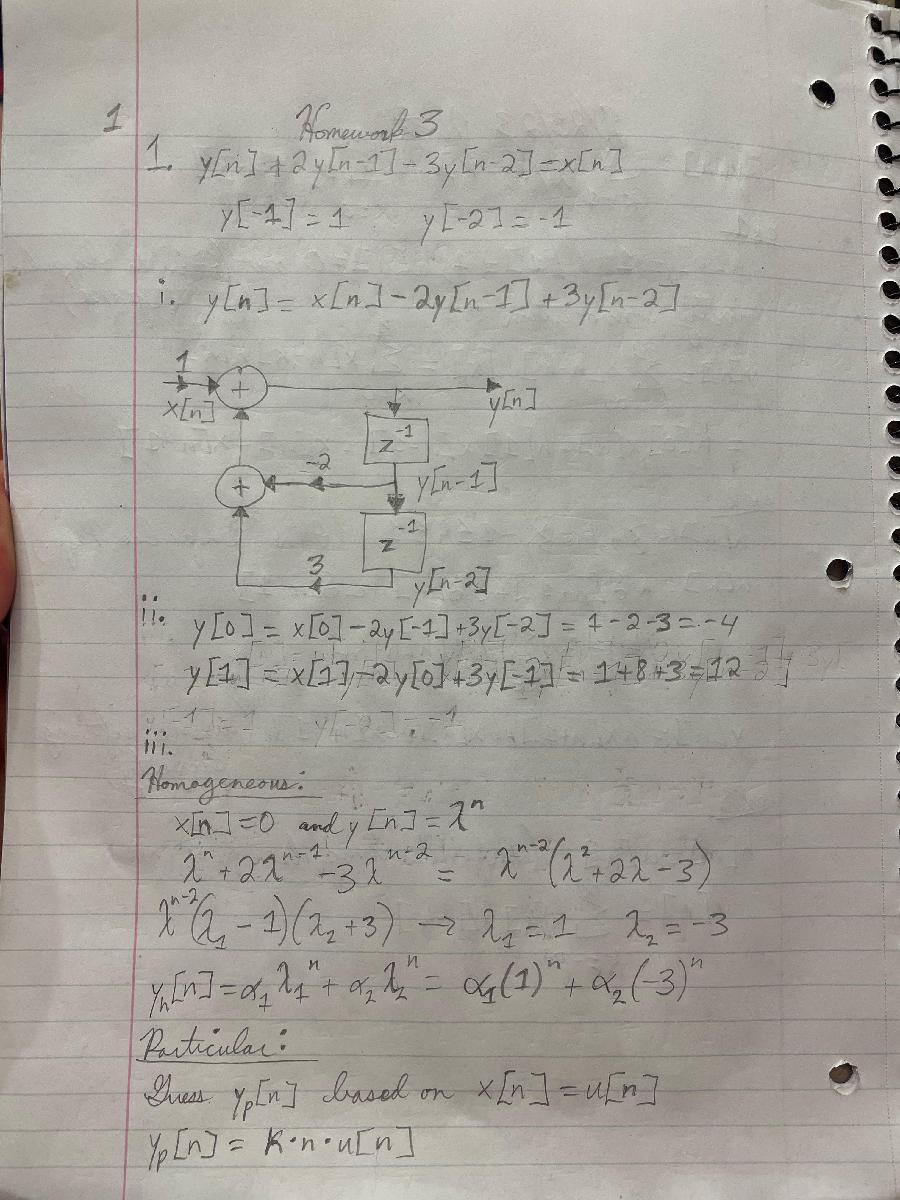

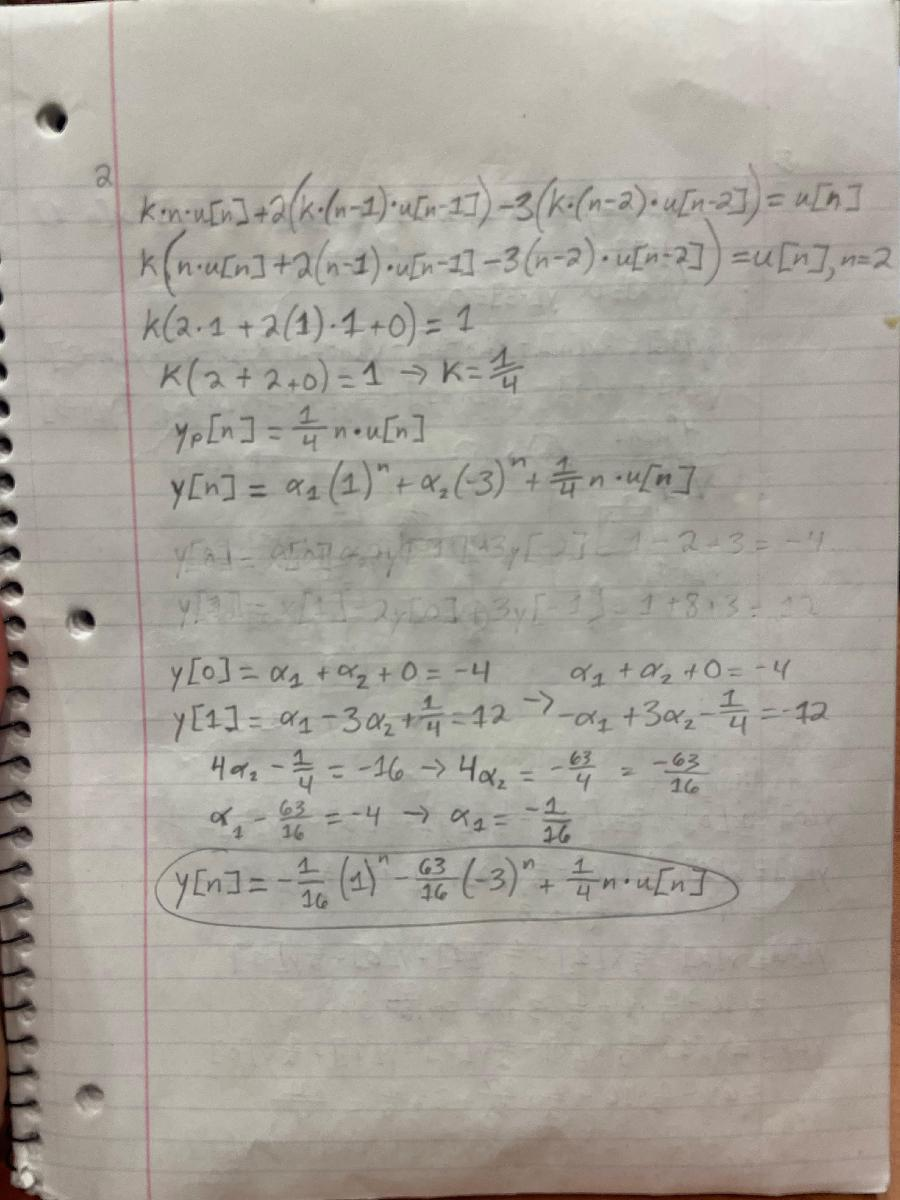

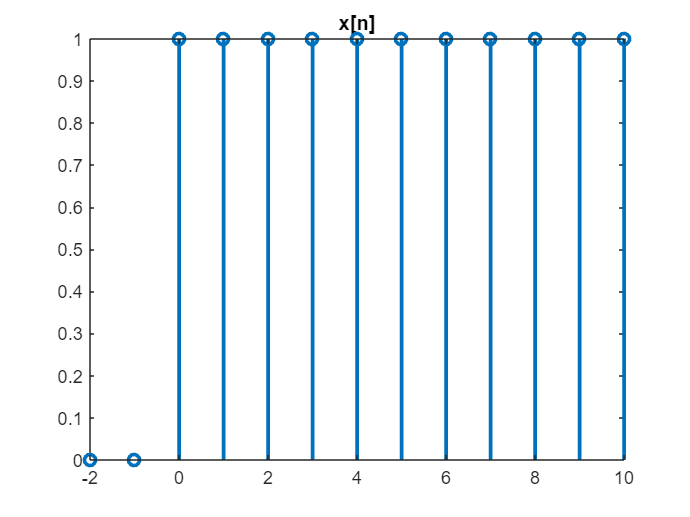

clear all, close all, clc

index = -2:10;
x=zeros(1,length(index));
y=zeros(1,length(index));

x(index > -1) = 1;
y(index == -2) = -1;
y(index == -1) = 1;
y(index == 0) = -4;

for i=1:index(end)
    y(index==i) = -2.*y(index==i-1)+3.*y(index==i-2)+x(index==i);
end

figure, stem(index, x, 'LineWidth', 2), title('x[n]')

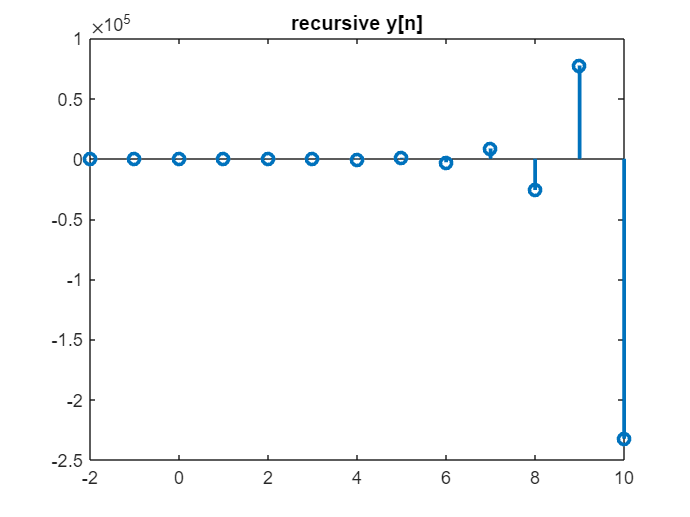

figure, stem(index, y, 'LineWidth', 2), title('recursive y[n]')

# Problem 2

An LTI system is described by the following difference equation:

2y[n] + y[n − 1] − 2y[n − 2] − y[n − 3] = 2x[n] − x[n − 1].

Assume that the system is initially at rest (i.e., y[n] = 0, when n < 0) and x[n] = 4nu[n]

i. [10 points] Represent the difference equation using a block diagram.

ii. [10 points] Determine the response (i.e., x[n] = u[n]) of the LTI system in a recursive manner. Write a MATLAB code that will use the initial conditions, the input and the previous values in y[n] sequence to generate y[n] for n=[1,10]. Plot y[n].

iii. [15 points] Determine the solution y[n], where y[n] is the complete solution of the system. (use analytical approach to find homogeneous and particular solution)

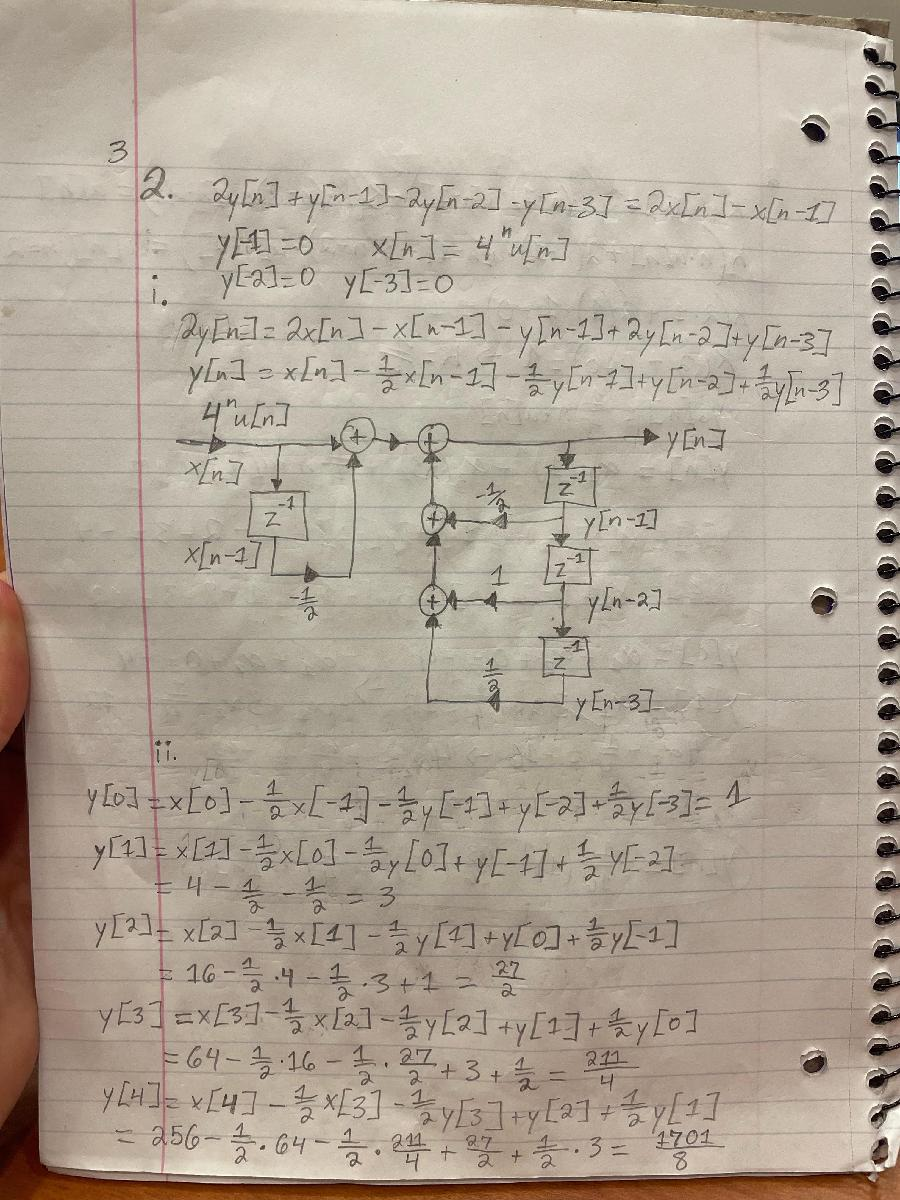

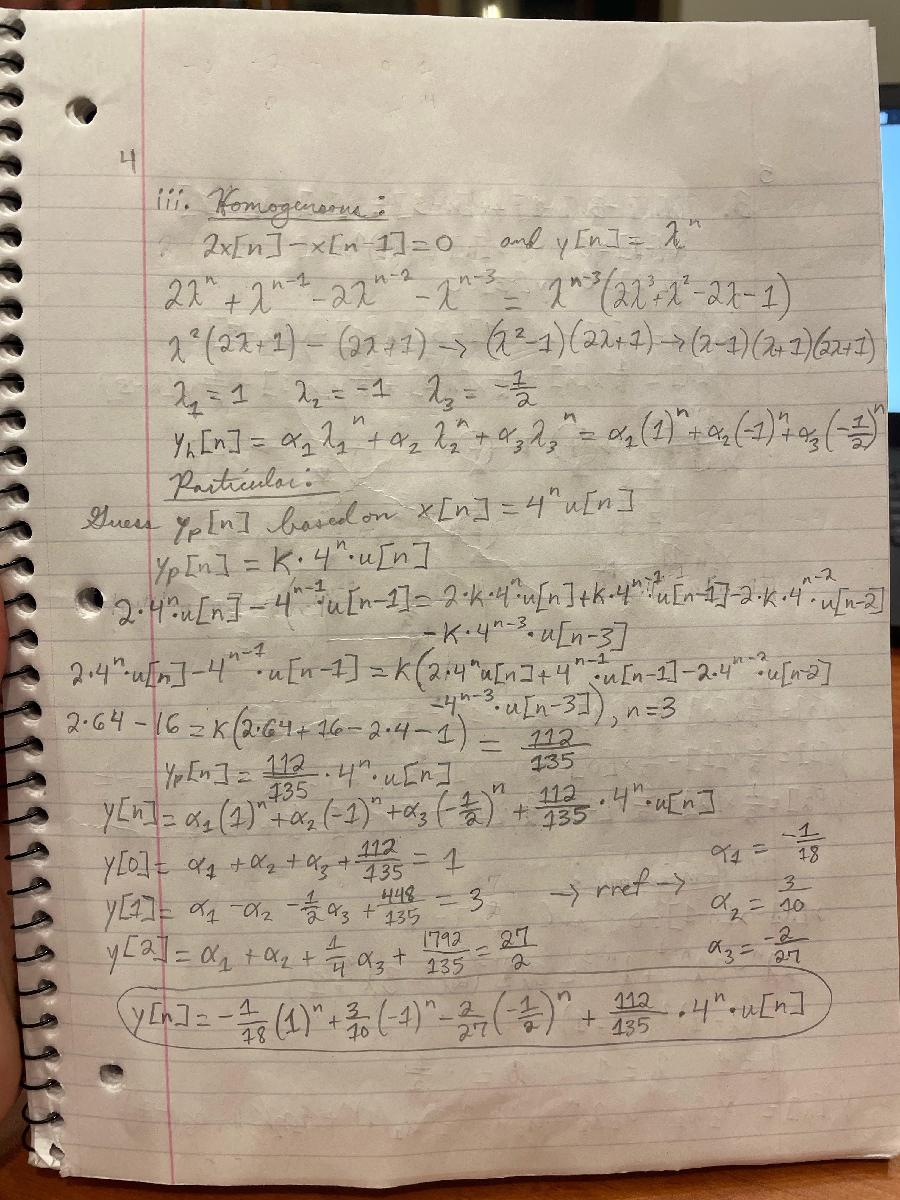

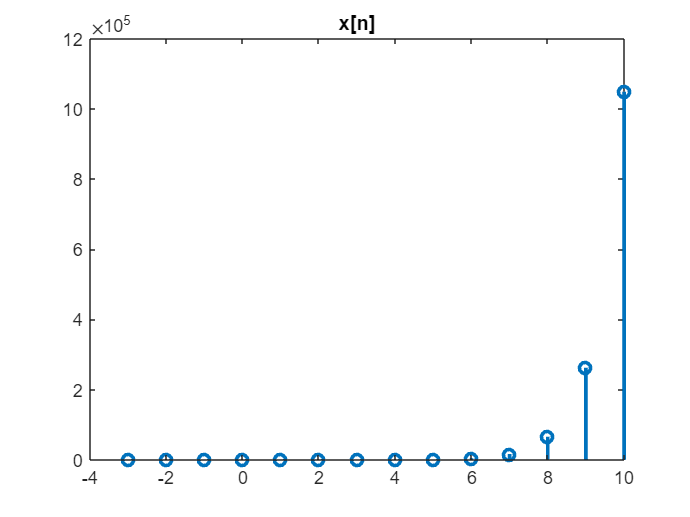

clear all, close all, clc

index = -3:10;
x=zeros(1,length(index));
y=zeros(1,length(index));

x(index < 0) = 0;
y(index == -2) = 0;
y(index == -1) = 0;
y(index == -3) = 0;

for i=4:14
    x(i) = 4^(i-4);
end

for i=0:index(end)
    y(index==i) = x(index==i) -0.5.*x(index==i-1) -0.5.*y(index==i-1) + 1.*y(index==i-2) + 0.5.*y(index==i-3);
end

figure, stem(index, x, 'LineWidth', 2), title('x[n]')

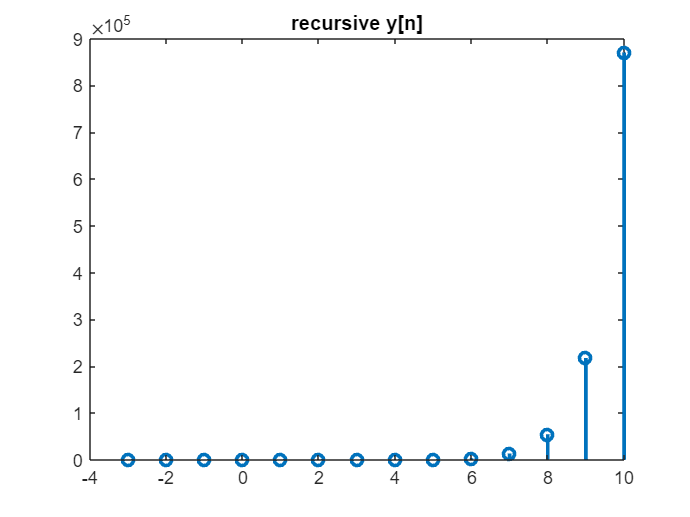

figure, stem(index, y, 'LineWidth', 2), title('recursive y[n]')

# Problem 3

An LTI system is described by the following difference equation: 

2y[n] − 3y[n − 1] + y[n − 3] = x[n] − x[n − 1].

Assume that the system is initially at rest (i.e., y[n] = 0, when n < 0) and x[n] = (−1)nu[n]

i. [10 points] Represent the difference equation using a block diagram.

ii. [10 points] Determine the response (i.e., x[n] = u[n]) of the LTI system in a recursive manner. Write a MATLAB code that will use the initial conditions, the input and the previous values in y[n] sequence to generate y[n] for n=[1,10]. Plot y[n].

iii. [15 points] Determine the solution y[n], where y[n] is the complete solution of the system (use analytical approach to find homogeneous and particular solution).

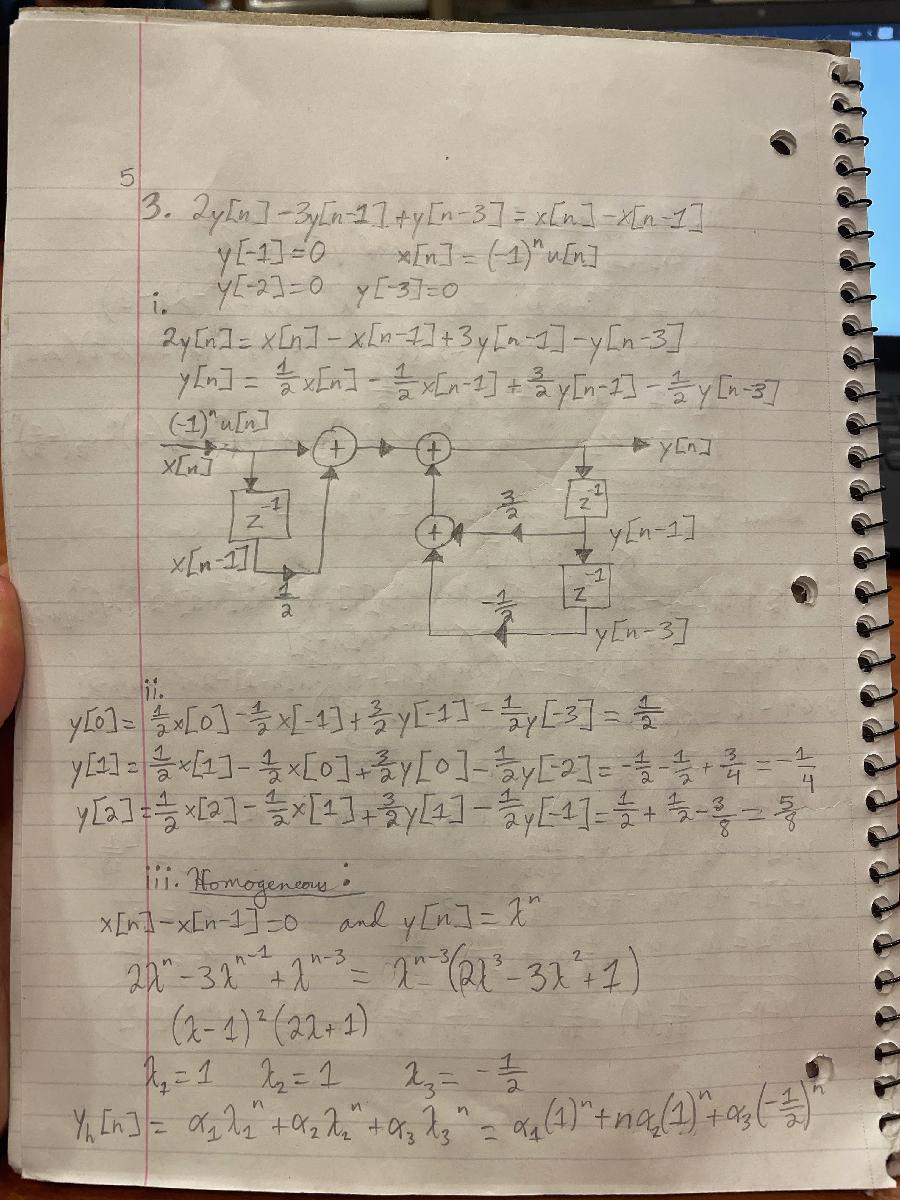

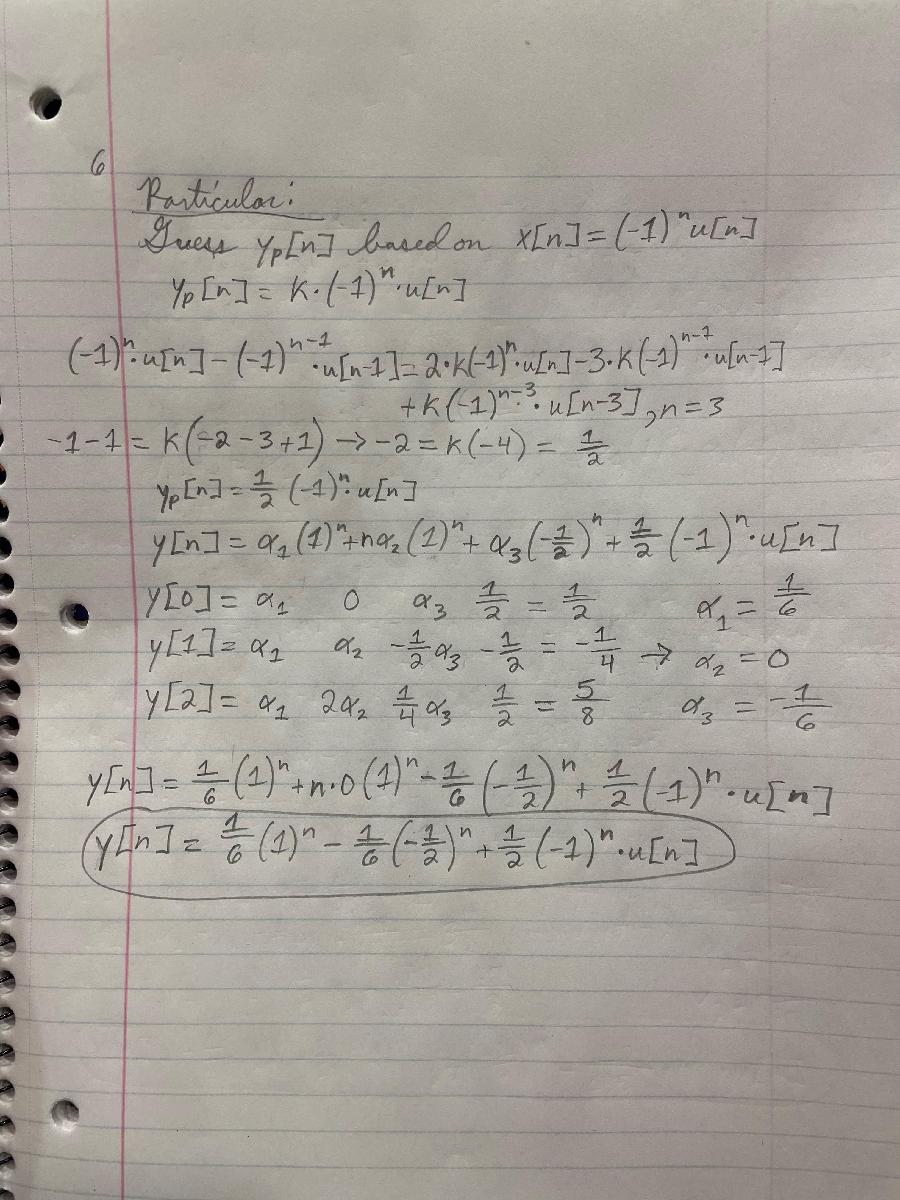

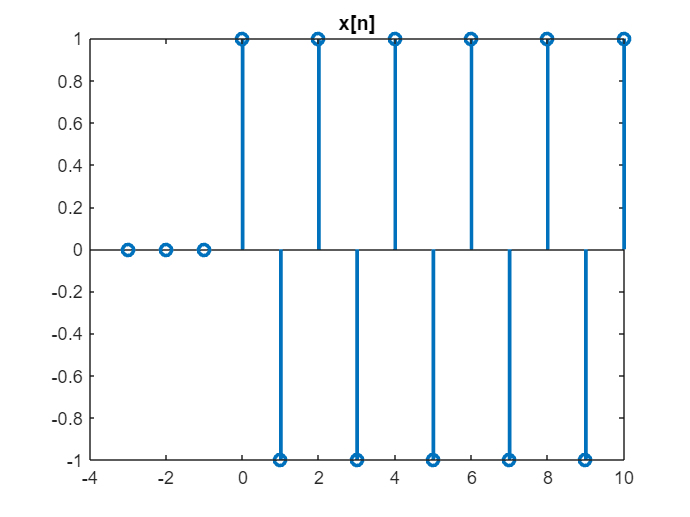

clear all, close all, clc

index = -3:10;
x=zeros(1,length(index));
y=zeros(1,length(index));

x(index < 0) = 0;
y(index == -2) = 0;
y(index == -1) = 0;
y(index == -3) = 0;

for i=4:14
    x(i) = (-1)^(i-4);
end

for i=0:index(end)
    y(index==i) = 0.5.*x(index==i) -0.5.*x(index==i-1) +1.5.*y(index==i-1) - 0.5.*y(index==i-3);
end

figure, stem(index, x, 'LineWidth', 2), title('x[n]')

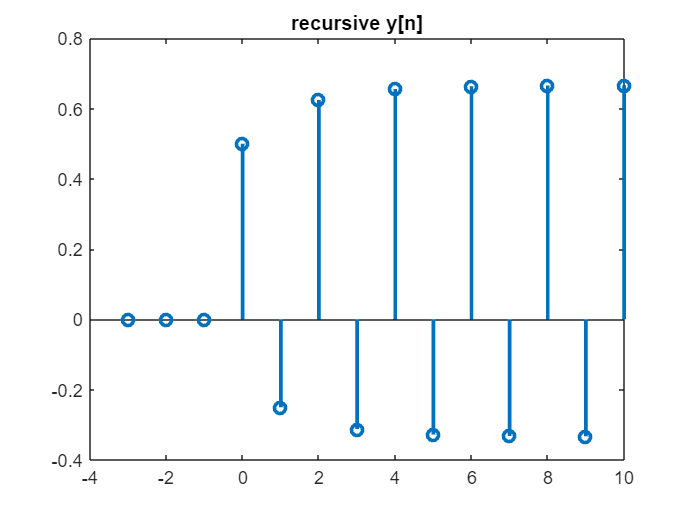

figure, stem(index, y, 'LineWidth', 2), title('recursive y[n]')

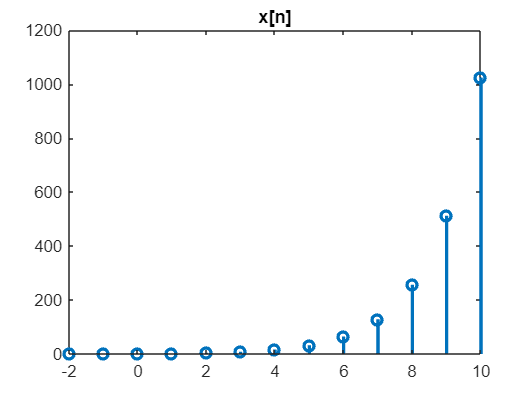

clear all, close all, clc

index = -2:10;
x=zeros(1,length(index));
y=zeros(1,length(index));

x(index < 0) = 0;
y(index == -2) = 0;
y(index == -1) = 1;

for i=3:13
    x(i) = (2)^(i-3);
end

for i=0:index(end)
    y(index==i) = x(index==i) -0.5.*y(index==i-1) +0.5.*y(index==i-2);
end

figure, stem(index, x, 'LineWidth', 2), title('x[n]')

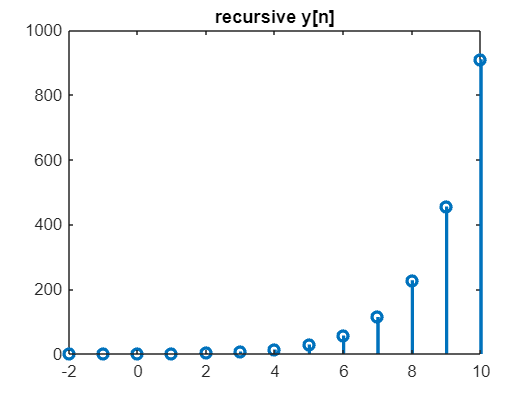

figure, stem(index, y, 'LineWidth', 2), title('recursive y[n]')